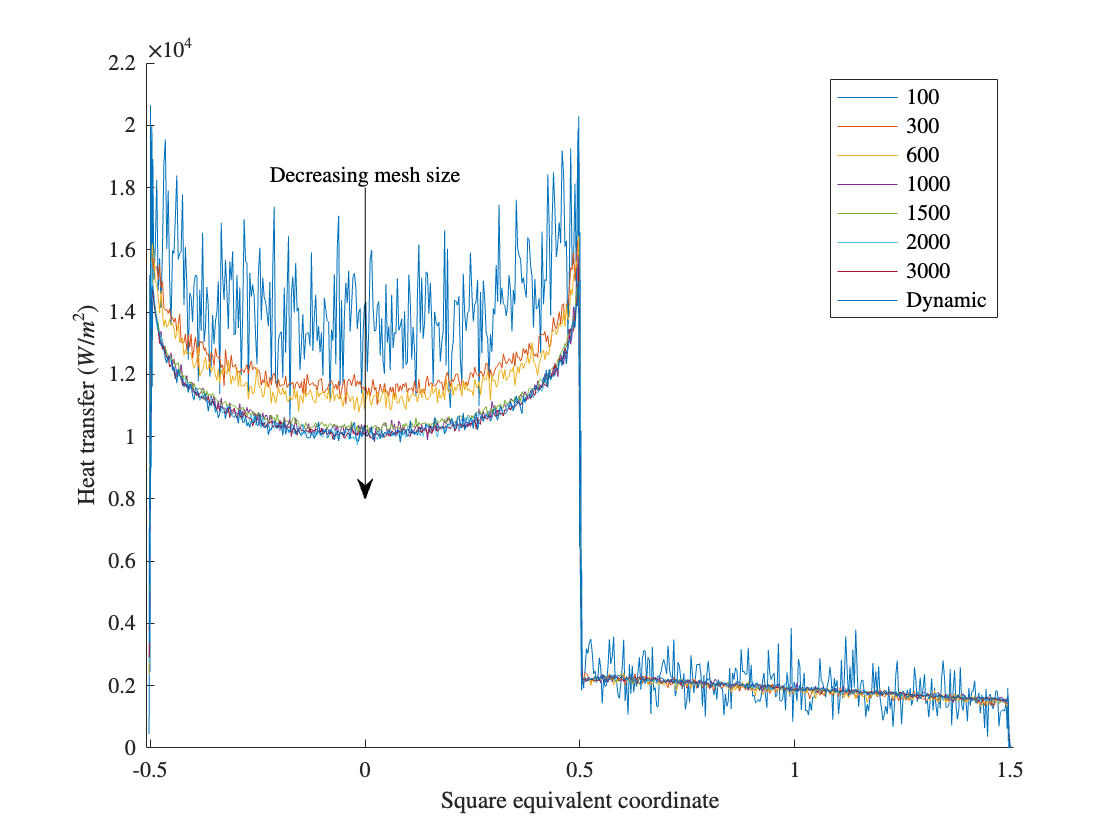

clear

% Mesh convergence study

%array prep

D100 = readmatrix('./mesh_convergence/surf100.txt');
D100 = sortrows(D100(8:1279,1:10),1);
D100 = [D100(end-14:end,:);D100(1:end-15,:)];
D100(:,1) = linspace(1,1272,1272);

D300 = readmatrix('./mesh_convergence/surf300.txt');
D300 = sortrows(D300(8:1279,1:10),1);
D300 = [D300(end-14:end,:);D300(1:end-15,:)];
D300(:,1) = linspace(1,1272,1272);

D600 = readmatrix('./mesh_convergence/surf600.txt');
D600 = sortrows(D600(8:1279,1:10),1);
D600 = [D600(end-14:end,:);D600(1:end-15,:)];
D600(:,1) = linspace(1,1272,1272);

D1000 = readmatrix('./mesh_convergence/surf1000.txt');
D1000 = sortrows(D1000(8:1279,1:10),1);
D1000 = [D1000(end-14:end,:);D1000(1:end-15,:)];
D1000(:,1) = linspace(1,1272,1272);

D1500 = readmatrix('./mesh_convergence/surf1500.txt');
D1500 = sortrows(D1500(8:1279,1:10),1);

D2000 = readmatrix('./mesh_convergence/surf2000.txt');
D2000 = sortrows(D2000(8:1279,1:10),1);

D3000 = readmatrix('./mesh_convergence/surf3000.txt');
D3000 = sortrows(D3000(8:1279,1:10),1);

DDynamic = readmatrix('./mesh_convergence/surfdynamic.txt');
DDynamic = sortrows(DDynamic(8:1279,1:10),1);

coords=coords('./AoA_results/squareroundhp2.txt');
coords = coords(1:651,:);

% plotting 

fig1=figure;
hold on
plot(coords(1:651,2),D100(1:651,10))
plot(coords(1:651,2),D300(1:651,10))
plot(coords(1:651,2),D600(1:651,10))
plot(coords(1:651,2),D1000(1:651,10))
plot(coords(1:651,2),D1500(1:651,10))
plot(coords(1:651,2),D2000(1:651,10))
plot(coords(1:651,2),D3000(1:651,10))
plot(coords(1:651,2),DDynamic(1:651,10))
legend('100','300','600','1000','1500','2000','3000','Dynamic','interpreter','latex','FontSize',11)
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Heat transfer ($W / m^2$)','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
ylim([0,2.2e4])
anArrow = annotation('textarrow','String','Decreasing mesh size','interpreter','latex','FontSize',11) ;
anArrow.Parent = gca;  
anArrow.Position = [0, 1.8e4, 0, -1e4] ;
exportgraphics(fig1,'../Images/3. Methodology/Mesh convergence/meshsec.pdf','ContentType','vector');


% mesh convergence graph

sp=170;

spheat=[D100(sp,10),D300(sp,10),D600(sp,10),D1000(sp,10),D1500(sp,10),D2000(sp,10),D3000(sp,10),DDynamic(sp,10)];
maxheat=[max(D100(310:320,10)),max(D300(310:320,10)),max(D600(310:320,10)),max(D1000(310:320,10)),max(D1500(310:320,10)),max(D2000(310:320,10)),max(D3000(310:320,10)),max(DDynamic(310:320,10))]

maxheat = 1.0e+04 *

    2.0287    1.6309    1.6460    1.5831    1.5357    1.4959    1.5378    1.4987


drag=[sum(D100(:,5)),sum(D300(:,5)),sum(D600(:,5)),sum(D1000(:,5)),sum(D1500(:,5)),sum(D2000(:,5)),sum(D3000(:,5)),sum(DDynamic(:,5))];
Cd=drag./(0.5*1.727e-5*1655^2*0.03)

Cd =     2.0658    2.0173    2.0097    1.9830    1.9861    1.9772    1.9771    1.9824


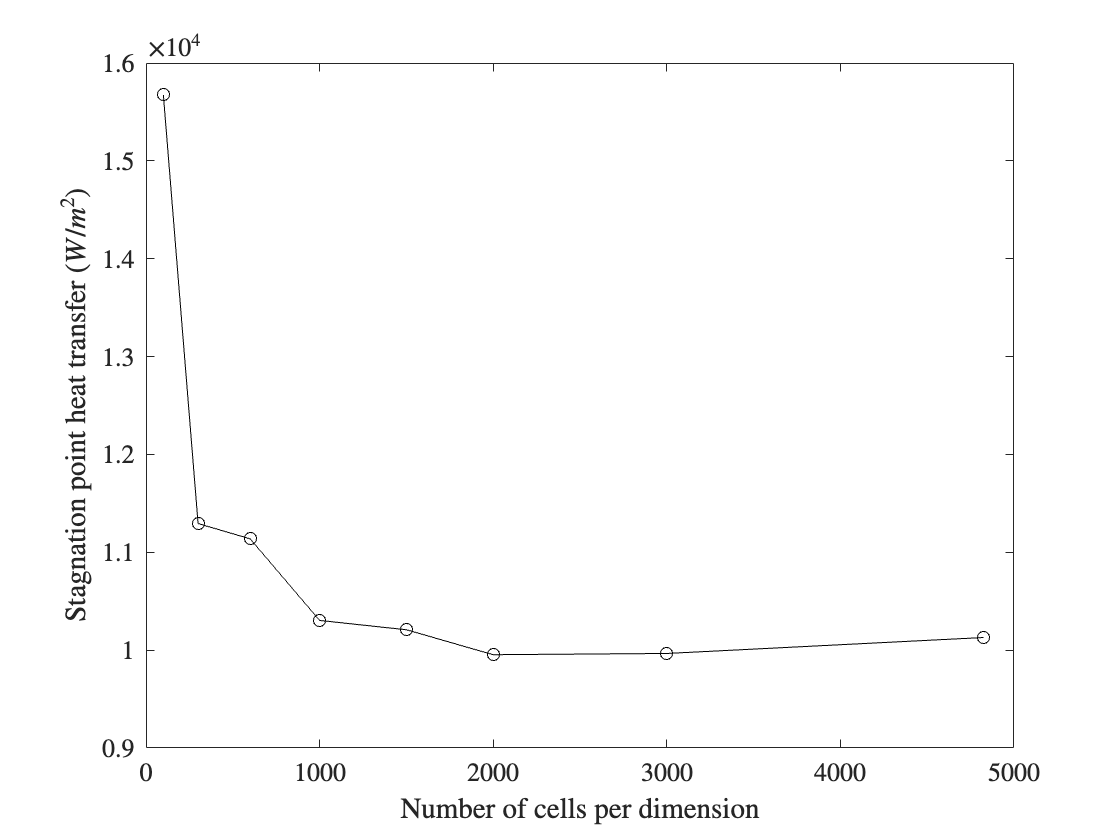


mesh=[100,300,600,1000,1500,2000,3000,4825];

% stagnation point heating
fig2=figure;
plot(mesh,spheat,'o-k')
xlabel('Number of cells per dimension','interpreter','latex','FontSize',13)
ylabel('Stagnation point heat transfer ($W / m^2$)','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig2,'../Images/3. Methodology/Mesh convergence/sphnc.pdf','ContentType','vector');

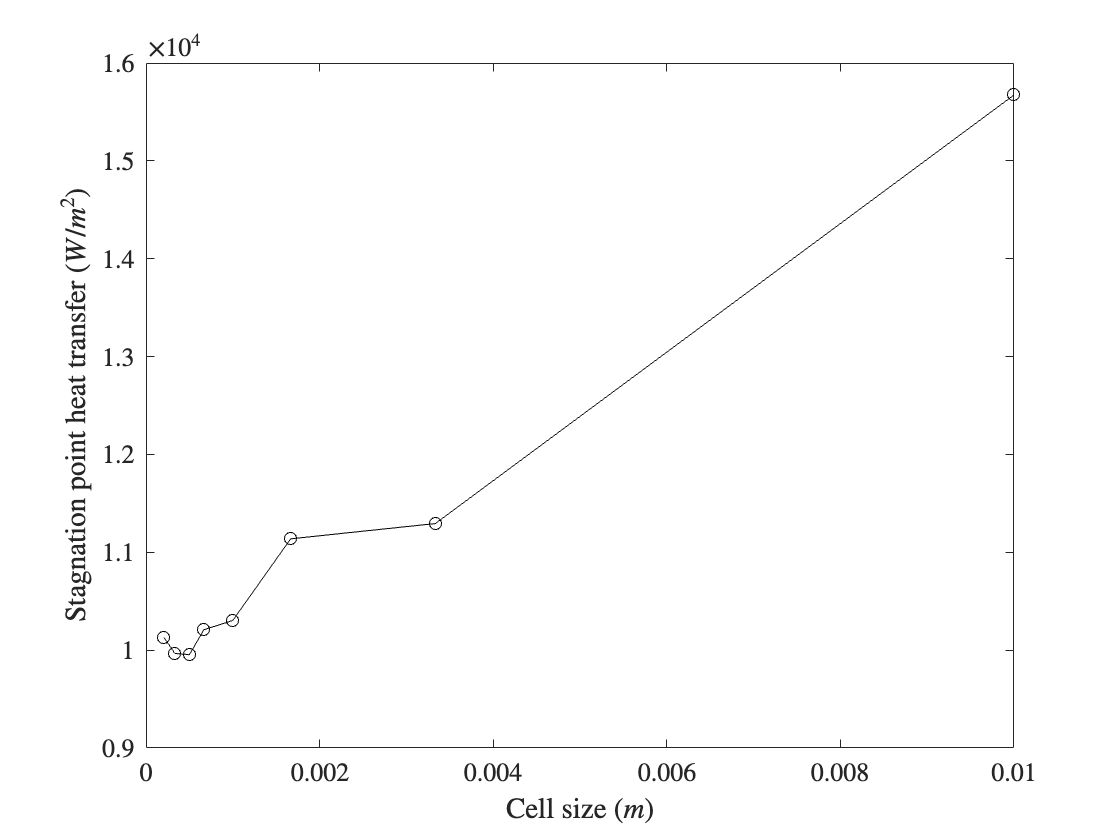


fig3=figure;
plot(1./mesh,spheat,'o-k')
xlabel('Cell size ($m$)','interpreter','latex','FontSize',13)
ylabel('Stagnation point heat transfer ($W / m^2$)','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig3,'../Images/3. Methodology/Mesh convergence/sphcs.pdf','ContentType','vector');

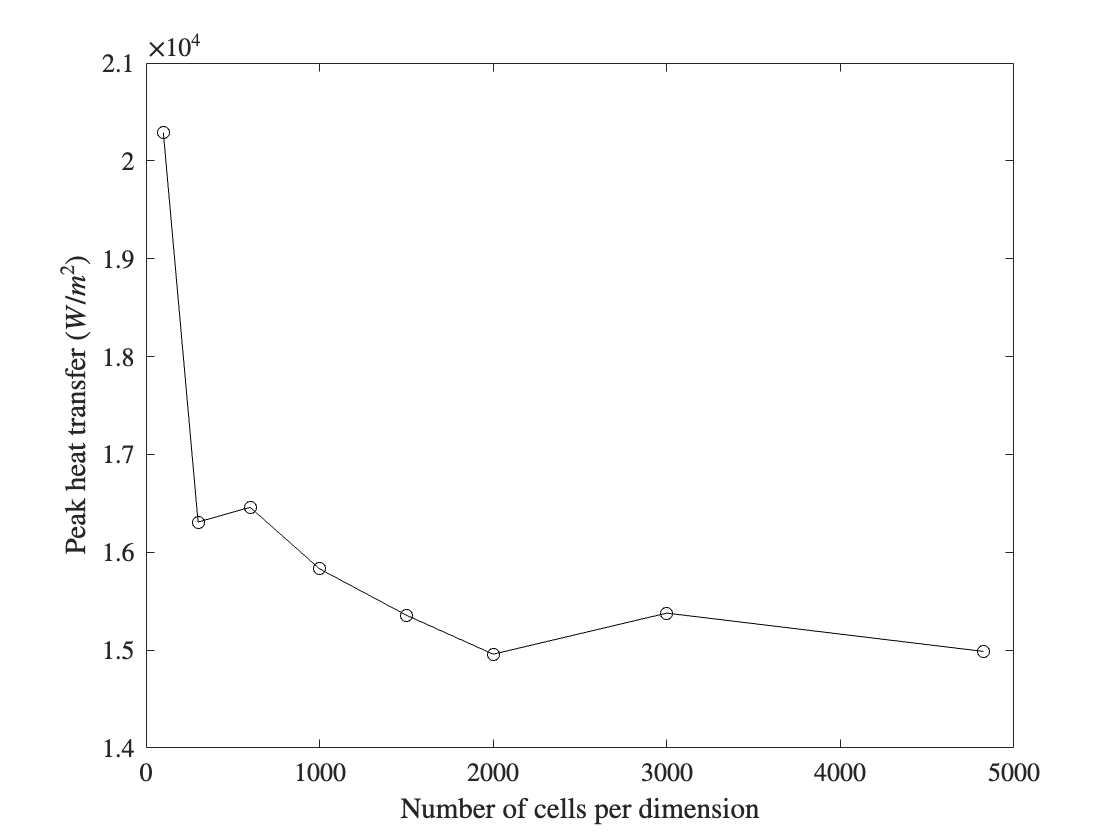



% peak heating
fig4=figure;
plot(mesh,maxheat,'o-k')
xlabel('Number of cells per dimension','interpreter','latex','FontSize',13)
ylabel('Peak heat transfer ($W / m^2$)','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig4,'../Images/3. Methodology/Mesh convergence/phnc.pdf','ContentType','vector');

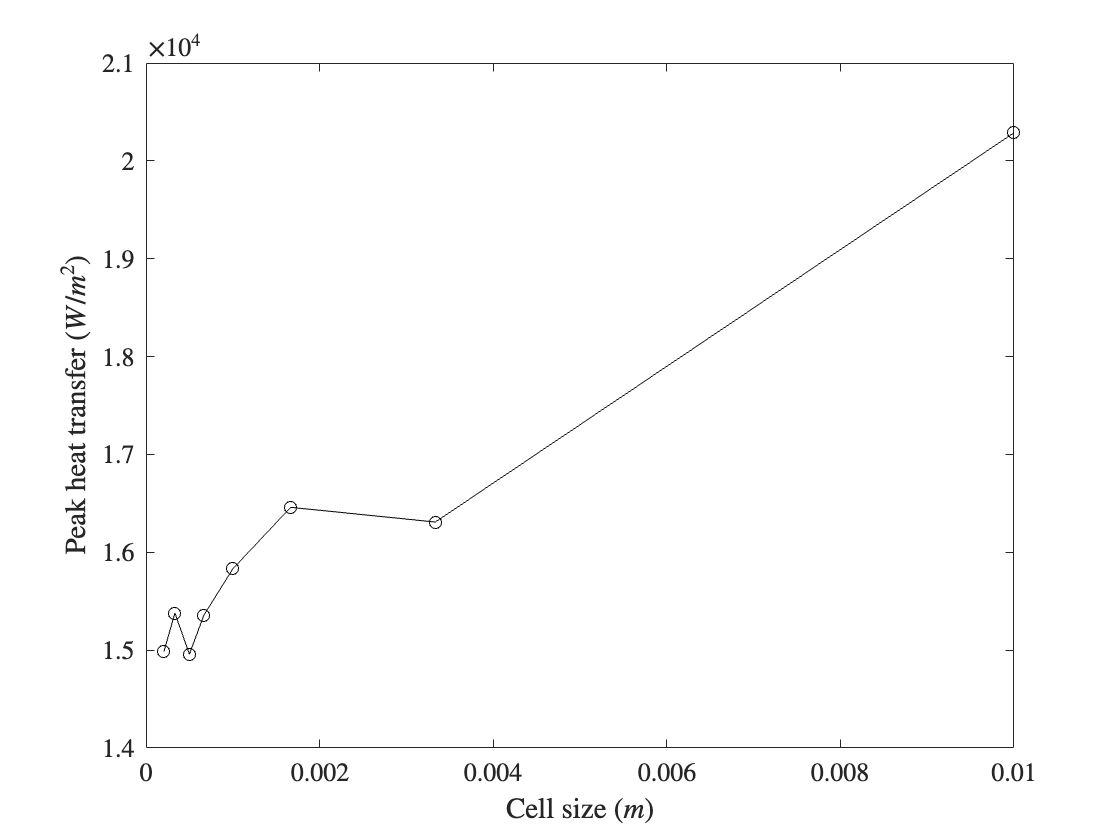


fig5=figure;
plot(1./mesh,maxheat,'o-k')
xlabel('Cell size ($m$)','interpreter','latex','FontSize',13)
ylabel('Peak heat transfer ($W / m^2$)','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig5,'../Images/3. Methodology/Mesh convergence/phcs.pdf','ContentType','vector');

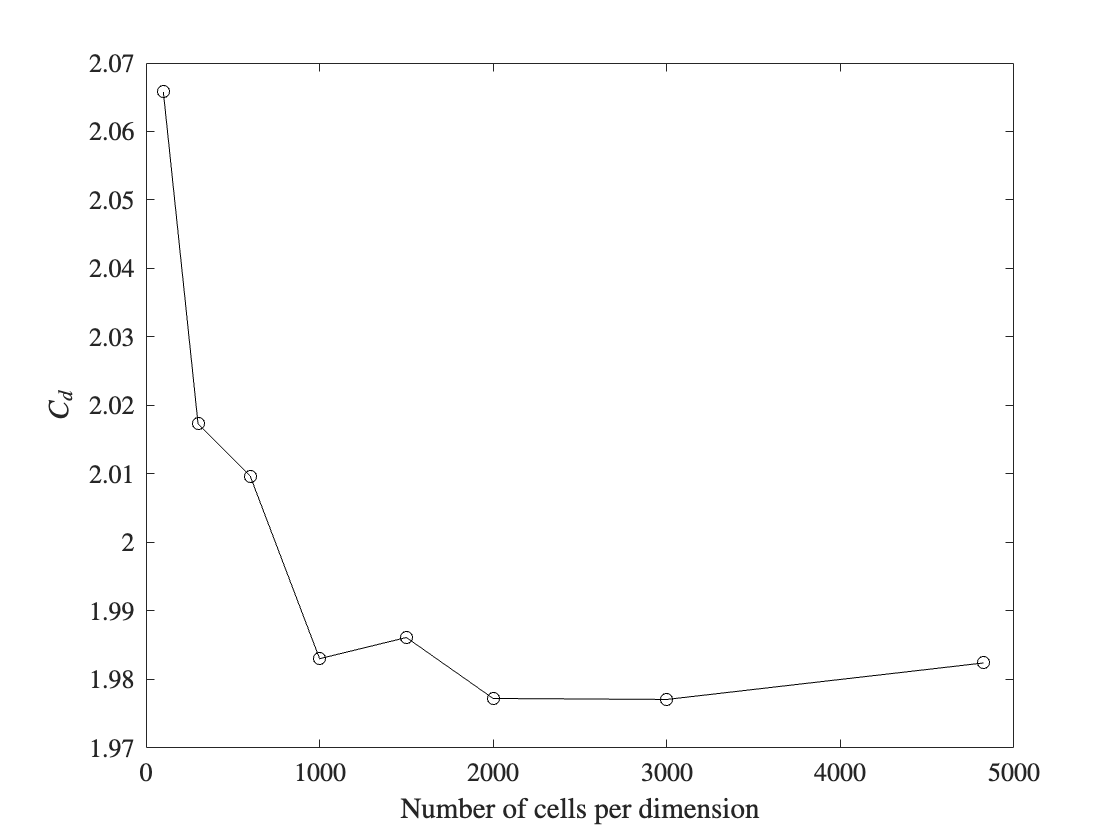



% drag coefficient
fig6=figure;
plot(mesh,Cd,'o-k')
xlabel('Number of cells per dimension','interpreter','latex','FontSize',13)
ylabel('$C_d$','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig6,'../Images/3. Methodology/Mesh convergence/cdnc.pdf','ContentType','vector');

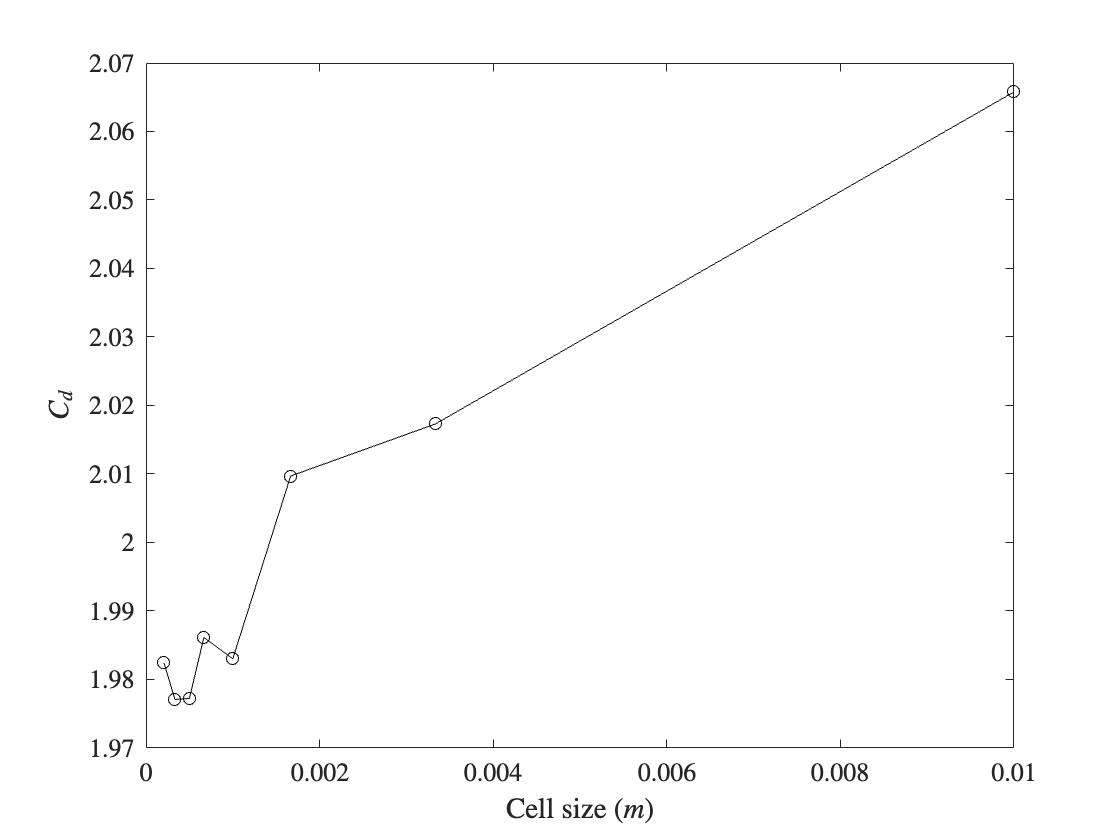


fig7=figure;
plot(1./mesh,Cd,'o-k')
xlabel('Cell size ($m$)','interpreter','latex','FontSize',13)
ylabel('$C_d$','interpreter','latex','FontSize',13)
set(gca,'TickLabelInterpreter','latex','FontSize',13)
exportgraphics(fig7,'../Images/3. Methodology/Mesh convergence/cdcs.pdf','ContentType','vector');